clear;
if exist('DataSet','dir')
   rmdir('.\DataSet\', 's');
end

mkdir('.\DataSet\');

% 配置
global run_type;
run_type = 'io';
config;

L_recTre = 119.0309


% 产生信号
source;
tag;
global y_sig;
y_sig = y_source;

% % dB 单位信噪比
% y_noise = awgn(y_sig, 50);
% y_sig = y_noise;

global Length;
global Width;

## 房间内的随机点(测试集)

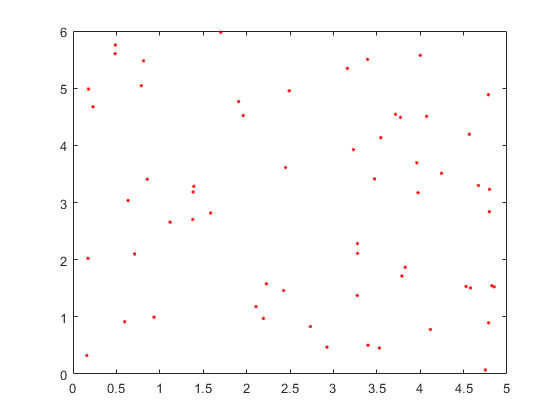

N_inside = 60;
x = Width * rand(1, N_inside);
y = Length * rand(1, N_inside);
% figure; plot(x,y,'r.');


% 计算三个距离
for j=1:2
    [d1, d2, d3] = xy2d(x, y,j, 'inside');
    single_run(d1, d2, d3, false, 'inside', j);
end

L_tag is
  列 1 至 16

  108.9214  110.2051  100.5712  110.1403  106.6393   94.9720  101.6913  105.4864  111.1730  110.9480   97.8245  111.0268  110.9663  104.3342  109.3080  100.4234

  列 17 至 32

  103.3976  110.3422  108.4331  110.5918  106.6624   96.5261  109.1767  110.2649  107.4748  108.1716  107.9317  102.5116  106.6296  100.6672  108.1396   97.6405

  列 33 至 48

  101.7101   97.6506   95.2076  109.5202  107.0841  102.1995  111.6781   99.8926  103.7048  102.2316  108.2307  108.4461   99.7715  104.2205  103.7387  106.4244

  列 49 至 60

  107.3488  108.0783  101.7694  107.7214  106.8560   97.0243   98.8705  104.2466  110.5890  101.6256  106.3326  101.2764

delta t is
   1.0e-07 *

  列 1 至 16

    0.1516    0.1764    0.0137    0.1745    0.1198    0.0260    0.0289    0.0986    0.2003    0.1923    0.0216    0.1942    0.1955    0.0747    0.1671    0.0174

  列 17 至 32

    0.0659    0.1794    0.1382    0.1817    0.1060    0.0120    0.1524    0.1747    0.1346    0.1351    0.1335    0.0532

Rate_miss = 0

L_tag is
  列 1 至 16

  108.9571  110.2220  100.6419  110.1684  106.7020   95.7130  101.7611  105.5063  111.1870  110.9639   98.1438  111.0425  110.9943  104.3598  109.3493  100.4659

  列 17 至 32

  103.4221  110.3589  108.4652  110.6125  106.6886   96.9340  109.2046  110.2883  107.5308  108.1924  107.9736  102.6157  106.6572  100.7530  108.1555   97.6616

  列 33 至 48

  101.7764   97.9341   95.8802  109.5357  107.1199  102.2518  111.6900   99.9348  103.7275  102.3513  108.2521  108.4745   99.7977  104.2768  103.7663  106.4695

  列 49 至 60

  107.3904  108.1188  101.8212  107.7378  106.8772   97.4662   98.8964  104.3340  110.6111  101.8219  106.3501  101.3295

delta t is
   1.0e-07 *

  列 1 至 16

    0.1522    0.1768    0.0145    0.1751    0.1206    0.0288    0.0297    0.0990    0.2007    0.1927    0.0234    0.1946    0.1961    0.0752    0.1677    0.0181

  列 17 至 32

    0.0664    0.1798    0.1388    0.1821    0.1065    0.0140    0.1529    0.1752    0.1354    0.1356    0.1341    0.0542

Rate_miss = 0

## 房间周围的随机点

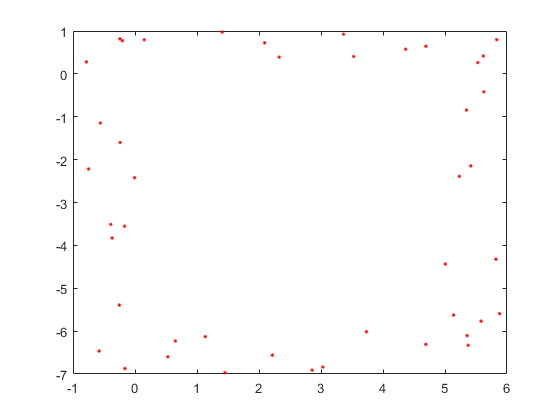

% 1/4 的数量
N_outside = 10;
x0 = rand(4, N_outside);
y0 = rand(4, N_outside);

x0 = [((Width / 2 + 1) * x0(:, 1:floor(N_outside / 2)))   (Width / 2 + x0(:, round(N_outside / 2) : end))];
y0 = [(Length / 2 + y0(:, 1:floor(N_outside / 2)))  ((Length / 2 + 1) * y0(:, round(N_outside / 2): end))];

x0(1,:) = -1 * x0(1, :);
x0(3,:) = -1 * x0(3, :);
y0(3,:) = -1 * y0(3, :);
y0(4,:) = -1 * y0(4, :);

% 坐标原点
x0 = x0 - (-1) * (Width / 2) * ones(size(x0));
y0 = y0 - 1 * (Length / 2) * ones(size(y0));

% 画出散点
figure; plot(x0,y0,'r.');


% 计算三个距离
for j=1:2
    [d1_0, d2_0, d3_0] = xy2d(x0, y0, j, 'outside');
    SinglePoint2(x0, y0, d1_0, d2_0, d3_0, false, 'outside', j);
end

  158.5039  157.9643  163.0315  163.9225  120.5333  119.8125  120.5551  120.3006  119.1064  120.1637  119.4120
  168.3058  162.4707  169.7192  177.1461  170.3273  227.8288  222.1172  221.3664  173.6615  216.3940  171.9383
  143.9789  163.0962  160.4240  153.3499  141.5279  120.0629  118.3797  119.9051  115.0439  119.6643  117.0592
  132.6411  167.4439  163.6945  167.6625  168.8266  229.4747  168.0265  213.2361  183.9051  227.1944  231.4335

delta t is
   1.0e-07 *

    0.0756    0.1151    0.1188    0.1073    0.0774    0.0606    0.0175    0.0749    0.0224    0.0108    0.0152
    0.2149    0.1685    0.1795    0.2985    0.2337    0.2561    0.2197    0.2322    0.2759    0.2077    0.2669
    0.0450    0.1024    0.1128    0.0591    0.0555    0.0106    0.0697    0.0093    0.0161    0.0105    0.0536
    0.1646    0.1586    0.2221    0.1538    0.2592    0.2468    0.2524    0.2291    0.2015    0.2568    0.2699

outside 1


Rate_miss = 0.9318

  158.5336  157.9940  163.0592  163.9496  120.5480  119.8295  120.5999  120.3156  119.1347  120.2154  119.4466
  168.3279  162.4964  169.7423  177.1633  170.3481  227.8507  222.1482  221.3913  173.6805  216.4278  171.9580
  144.6008  163.2844  160.5425  153.8937  141.8855  120.1624  118.8665  120.0094  115.6919  119.7910  117.6430
  132.6888  167.5099  163.7250  167.7346  168.8501  229.5119  168.0502  213.2872  183.9545  227.2380  231.4728

delta t is
   1.0e-07 *

    0.0760    0.1155    0.1192    0.1077    0.0778    0.0610    0.0181    0.0753    0.0229    0.0115    0.0158
    0.2153    0.1689    0.1798    0.2988    0.2340    0.2564    0.2201    0.2325    0.2762    0.2081    0.2672
    0.0475    0.1038    0.1139    0.0615    0.0574    0.0116    0.0719    0.0103    0.0187    0.0116    0.0560
    0.1653    0.1594    0.2227    0.1546    0.2597    0.2473    0.2529    0.2296    0.2020    0.2573    0.2703

outside 2


Rate_miss = 0.9318

## 上下房间

N_up = 20;
x_u = Width * rand(1, N_up);
y_u = Length * rand(1, N_up);
figure; plot(x,y,'r.');


% 计算三个距离
for j=1:2
    [d1_u, d2_u, d3_u] = xy2d(x, y,j, 'up');
    single_run(d1_u, d2_u, d3_u, false, 'up', j);
end

L_tag is
  列 1 至 16

  128.8676  130.0111  120.2195  130.0718  126.6644  116.5917  121.4608  124.9115  130.9797  130.7767  118.4361  130.8568  130.9230  123.7645  129.3012  119.5548

  列 17 至 32

  122.6165  130.1514  128.3320  130.4698  126.3796  117.3406  129.0703  130.1588  127.4928  127.9150  127.8842  122.5644  126.3663  120.4673  127.7626  111.2116

  列 33 至 48

  121.4490  118.1360  116.6702  129.2536  126.9498  121.8383  131.4677  118.8666  122.9085  122.3422  127.9897  128.3104  117.7427  124.0869  123.1305  126.3336

  列 49 至 60

  127.2753  128.0266  121.3454  127.3171  126.4919  117.9593  116.1271  124.3017  130.4834  121.9985  125.7910  120.8004

delta t is
   1.0e-07 *

  列 1 至 16

    0.1497    0.1730    0.0092    0.1725    0.1185    0.0293    0.0252    0.0925    0.1969    0.1892    0.0222    0.1910    0.1938    0.0688    0.1657    0.0101

  列 17 至 32

    0.0589    0.1761    0.1358    0.1790    0.1020    0.0131    0.1499    0.1723    0.1333    0.1313    0.1316    0.0516

Rate_miss = 0.8333

L_tag is
  列 1 至 16

  128.8257  129.9912  120.1378  130.0388  126.5916  115.9041  121.3801  124.8880  130.9632  130.7580  118.0976  130.8383  130.8900  123.7344  129.2530  119.5052

  列 17 至 32

  122.5876  130.1317  128.2943  130.4455  126.3488  116.9208  129.0375  130.1313  127.4276  127.8905  127.8351  122.4454  126.3339  120.3686  127.7439  111.1867

  列 33 至 48

  121.3722  117.8318  116.0331  129.2353  126.9079  121.7774  131.4537  118.8173  122.8818  122.2062  127.9644  128.2770  117.7120  124.0215  123.0980  126.2809

  列 49 至 60

  127.2266  127.9793  121.2851  127.2978  126.4669  117.5096  116.0967  124.2011  130.4573  121.7814  125.7704  120.7386

delta t is
   1.0e-07 *

  列 1 至 16

    0.1490    0.1725    0.0082    0.1719    0.1175    0.0264    0.0242    0.0920    0.1965    0.1887    0.0201    0.1906    0.1932    0.0682    0.1649    0.0093

  列 17 至 32

    0.0583    0.1756    0.1351    0.1785    0.1013    0.0108    0.1493    0.1717    0.1325    0.1307    0.1308    0.0504

Rate_miss = 0.8333


N_dn = 20;
x_d = Width * rand(1, N_dn);
y_d = Length * rand(1, N_dn);
figure; plot(x,y,'r.');


% 计算三个距离
for j=1:2
    [d1_d, d2_d, d3_d] = xy2d(x, y,j, 'down');
    single_run(d1_d, d2_d, d3_d, false, 'down', j);
end

L_tag is
  列 1 至 16

  132.7666  133.6820  128.2817  133.5348  131.6153  128.8787  128.7668  131.2183  134.4012  134.1752  128.5727  134.2306  134.1349  130.4396  133.1428  128.5465

  列 17 至 32

  130.1854  133.7750  132.4023  133.8367  131.4295  128.3210  132.8750  133.6013  132.0874  132.3804  132.1674  129.4949  131.3801  128.3524  132.6503  129.4506

  列 33 至 48

  128.7689  128.2187  128.7592  133.3667  131.5669  129.0118  134.8450  128.4137  130.4136  129.5091  132.3901  132.4058  129.2090  129.9993  130.1270  131.2164

  列 49 至 60

  131.7727  132.2477  128.8399  132.4155  131.7092  128.8344  129.0910  130.3781  133.8243  130.0236  131.7444  128.6380

delta t is
   1.0e-07 *

  列 1 至 16

    0.2364    0.2575    0.1342    0.2546    0.2139    0.1635    0.1442    0.2004    0.2782    0.2706    0.1512    0.2721    0.2725    0.1806    0.2505    0.1398

  列 17 至 32

    0.1764    0.2600    0.2250    0.2605    0.2010    0.1462    0.2363    0.2546    0.2254    0.2243    0.2222    0.1645

Rate_miss = 1

L_tag is
  列 1 至 16

  132.8659  133.7421  128.4213  133.6204  131.7480  129.1027  128.9057  131.2862  134.4533  134.2325  128.7793  134.2875  134.2204  130.5203  133.2505  128.6559

  列 17 至 32

  130.2638  133.8344  132.4954  133.9062  131.5113  128.5339  132.9604  133.6771  132.2134  132.4504  132.2760  129.6562  131.4647  128.5031  132.7076  129.5213

  列 33 至 48

  128.9048  128.4219  128.9818  133.4229  131.6663  129.1337  134.8907  128.5227  130.4878  129.6775  132.4615  132.4921  129.2907  130.1255  130.2117  131.3294

  列 49 至 60

  131.8809  132.3543  128.9611  132.4742  131.7801  129.0491  129.1721  130.5299  133.8974  130.2140  131.8060  128.7608

delta t is
   1.0e-07 *

  列 1 至 16

    0.2386    0.2592    0.1368    0.2567    0.2164    0.1668    0.1468    0.2022    0.2798    0.2723    0.1543    0.2738    0.2746    0.1826    0.2528    0.1421

  列 17 至 32

    0.1784    0.2617    0.2271    0.2623    0.2030    0.1494    0.2383    0.2565    0.2279    0.2261    0.2245    0.1673

Rate_miss = 1

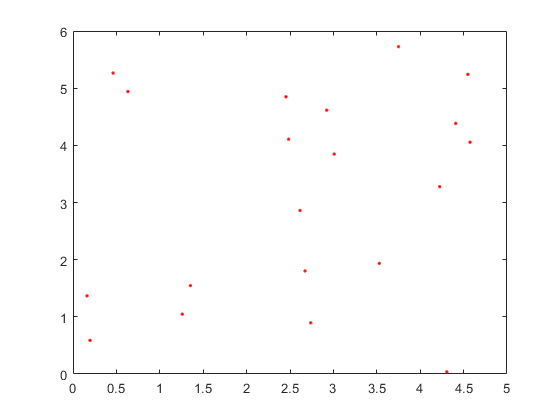

% 画出散点
% figure; plot(x_u,y_u,'r.');

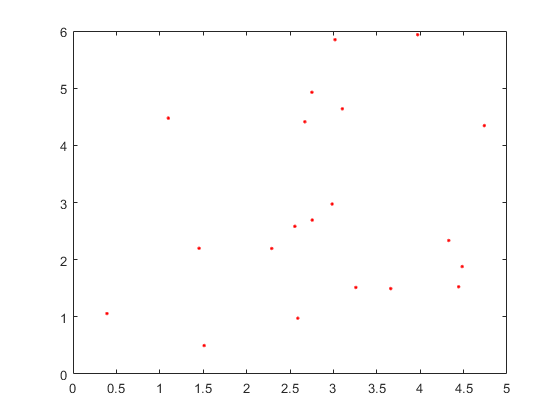

% figure; plot(x_d,y_d,'r.');

## 保存数据集的信息

% 保存样本点
filename = '.\DataSet\sample.mat'

filename = '.\DataSet\sample.mat'

save(filename, 'N_inside', 'N_outside', 'N_up', 'N_dn',...
    'x', 'y', 'd1', 'd2', 'd3', ...
    'x0', 'y0', 'd1_0', 'd2_0', 'd3_0', ...
    'x_u', 'y_u', 'd1_u', 'd2_u', 'd3_u', ...
    'x_d', 'y_d', 'd1_d', 'd2_d', 'd3_d');

## 数据预处理

% [] = preproc(filename, i, draw, isBeacon)
for i=1: N_inside
    preproc('i_sig_rx', i, false, 'inside');
end

% outside
for i=1: 4 * N_outside
    preproc('o_sig_rx', i, false, 'outside');
end

% up
for i=1: N_up
    preproc('u_sig_rx', i, false, 'up');
end

% down
for i=1: N_dn
    preproc('d_sig_rx', i, false, 'down');
end